# Machine Learning: Programming Exercise 7

## *K*-Means Clustering and Principal Component Analysis

In this exercise, you will implement the *K*-means clustering algorithm and apply it to compress an image. In the second part, you will use principal component analysis to find a low-dimensional representation of face images.

### Files needed for this exercise

- `ex7.mlx` - MATLAB Live Script that steps you through the exercise

- `ex7data1.mat` - Example Dataset for PCA

- `ex7data2.mat` - Example Dataset for K-means

- `ex7faces.mat` - Faces Dataset

- bird small.png - Example Image

- `displayData.m` - Displays 2D data stored in a matrix

- `drawLine.m` - Draws a line over an exsiting figure

- `plotDataPoints.m` - Initialization for K-means centroids

- `plotProgresskMeans.m` - Plots each step of K-means as it proceeds

- `runkMeans.m` - Runs the K-means algorithm

- `submit.m` - Submission script that sends your solutions to our servers

- *`pca.m` - Perform principal component analysis

- *`projectData.m` - Projects a data set into a lower dimensional space

- *`recoverData.m` - Recovers the original data from the projection

- *`findClosestCentroids.m` - Find closest centroids (used in K-means)

- *`computeCentroids.m` - Compute centroid means (used in K-means)

- *`kMeansInitCentroids.m` - Initialization for K-means centroids

****indicates files you will need to complete***

#### Confirm that your Current Folder is set correctly

Click into this section, then click the 'Run section' button above. This will execute the `dir` command below to list the files in your Current Folder. The output should contain all of the files listed above and the 'lib' folder. If it does not, right-click the 'ex7' folder and select 'Open' before proceding or see the instructions in `README.mlx` for more details.

dir

.                       computeCentroids.m      ex7_companion.mlx       featureNormalize.m      pca.m                   recoverData.m           
..                      displayData.m           ex7data1.mat            findClosestCentroids.m  plotDataPoints.m        runkMeans.m             
bird_small.mat          drawLine.m              ex7data2.mat            kMeansInitCentroids.m   plotProgresskMeans.m    submit.m                
bird_small.png          ex7.mlx                 ex7faces.mat            lib                     projectData.m           token.mat               



### Before you begin

The workflow for completing and submitting the programming exercises in MATLAB Online differs from the original course instructions. Before beginning this exercise, make sure you have read through the instructions in `README.mlx` which is included with the programming exercise files. `README` also contains solutions to the many common issues you may encounter while completing and submitting the exercises in MATLAB Online. Make sure you are following instructions in `README` and have checked for an existing solution before seeking help on the discussion forums.

## 1. *K*-Means Clustering

In this this exercise, you will implement the *K*-means algorithm and use it for image compression. You will first start on an example 2D dataset that will help you gain an intuition of how the *K*-means algorithm works. After that, you wil use the *K*-means algorithm for image compression by reducing the number of colors that occur in an image to only those that are most common in that image.

### 1.1 Implementing *K*-means

The K-means algorithm is a method to automatically cluster similar data examples together. Concretely, you are given a training set $\{x^{(1)},\ldots x^{(m)}\}$ (where $x^{(i)}\in \mathbb{R}^n$), and want to group the data into a few cohesive 'clusters'. The intuition behind *K*-means is an iterative procedure that starts by guessing the initial centroids, and then refines this guess by repeatedly assigning examples to their closest centroids and then recomputing the centroids based on the assignments.

    The *K*-means algorithm is as follows:

The inner-loop of the algorithm repeatedly carries out two steps: 

- Assigning each training example $x^{(i)}$ to its closest centroid

- Recomputing the mean of each centroid using the points assigned to it. 

The *K*-means algorithm will always converge to some final set of means for the centroids. Note that the converged solution may not always be ideal and depends on the initial setting of the centroids. Therefore, in practice the K-means algorithm is usually run a few times with dierent random initializations. One way to choose between these different solutions from different random initializations is to choose the one with the lowest cost function value (distortion). You will implement the two phases of the K-means algorithm separately in the next sections.

#### 1.1.1 Finding closest centroids

In the 'cluster assignment' phase of the *K*-means algorithm, the algorithm assigns every training example $x^{(i)}$ to its closest centroid, given the current positions of centroids. Specically, for every example $i$ we set 


$$c^{(i)} :=j \quad\text{that minimizes}\quad\left||x^{(i)}-\mu_j\right||^2,$$


where $c^{(i)}$ is the index of the centroid that is closest to $x^{(i)}$, and $\mu_j$ is the position (value) of the $j$-th centroid. Note that $c^{(i)}$ corresponds to `idx(i)` in the starter code.

    Your task is to complete the code in `findClosestCentroids.m`. This function takes the data matrix `X` and the locations of all centroids inside centroids and should output a one-dimensional array `idx` that holds the index (a value in $\{1,\ldots,K\}$, where $K$ is total number of centroids) of the closest centroid to every training example. You can implement this using a loop over every training example and every centroid. 

    Once you have completed the code in `findClosestCentroids.m`, the code below will run your code and you should see the output `[1 3 2]` corresponding to the centroid assignments for the first 3 examples.

% Load an example dataset that we will be using
load('ex7data2.mat');

% Select an initial set of centroids
K = 3; % 3 Centroids
initial_centroids = [3 3; 6 2; 8 5];

% Find the closest centroids for the examples using the initial_centroids
idx = findClosestCentroids(X, initial_centroids);
fprintf('Closest centroids for the first 3 examples: %d %d %d', idx(1:3))

Closest centroids for the first 3 examples: 1 3 2

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 1.1.2 Computing centroid means

Given assignments of every point to a centroid, the second phase of the algorithm recomputes, for each centroid, the mean of the points that were assigned to it. Specically, for every centroid $k$ we set


$$\mu_k := \frac{1}{|C_k|}\sum_{i\in C_k}{x^{(i)}}$$


where $C_k$ is the set of examples that are assigned to centroid $k$. Concretely, if two examples say $x^{(3)}$ and $x^{(5)}$ are assigned to centroid $k = 2$, then you should update $\mu_2 = \frac{1}{2} (x^{(3)} + x^{(5)})$. You should now complete the code in `computeCentroids.m`. You can implement this function using a loop over the centroids. You can also use a loop over the examples; but if you can use a vectorized implementation that does not use such a loop, your code may run faster. Once you have completed the code in `computeCentroids.m`, the code below will run your code and output the centroids after the first step of *K*-means. The centroids should be:

- `[ 2.428301 3.157924 ]`

- `[ 5.813503 2.633656 ]`

- `[ 7.119387 3.616684 ]`

% Compute means based on the closest centroids found in the previous part.
centroids = computeCentroids(X, idx, K);
fprintf('Centroids computed after initial finding of closest centroids: \n %f %f \n %f %f\n %f %f' , centroids');

Centroids computed after initial finding of closest centroids: 
 2.428301 3.157924 
 5.813503 2.633656
 7.119387 3.616684

*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 1.2 K-means on example dataset

After you have completed the two functions (`findClosestCentroids` and `computeCentroids`), the code below will run the *K*-means algorithm on a toy 2D dataset to help you understand how *K*-means works. Your functions are called from inside the `runKmeans.m` script. We encourage you to take a look at the function to understand how it works. Notice that the code calls the two functions you implemented in a loop.

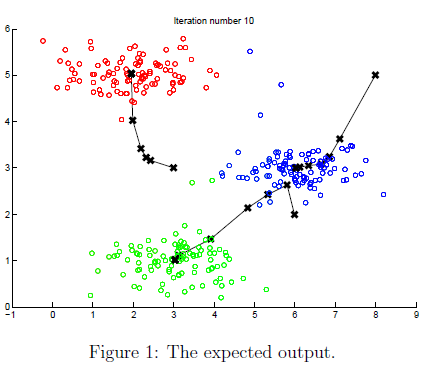

    When you run the next step, the *K*-means code will produce a visualization that steps you through the progress of the algorithm at each iteration. 

**At the command line**, **press enter multiple times to see how each step of the *****K*****-means algorithm changes the centroids and cluster assignments.** 

At the end, your figure should look as the one displayed in Figure 1.

% Load an example dataset
load('ex7data2.mat');
% Settings for running K-Means

max_iters = 10;

For consistency, here we set centroids to specific values but in practice you want to generate them automatically, such as by setting them to be random examples (as can be seen in `kMeansInitCentroids`).

K-Means iteration 1/10...


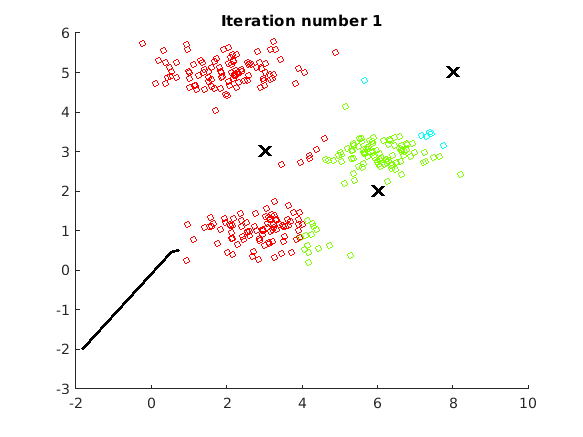

Press enter to continue.


initial_centroids = [3 3; 6 2; 8 5];

% Run K-Means algorithm. The 'true' at the end tells our function to plot the progress of K-Means
figure('visible','on'); hold on; 
plotProgresskMeans(X, initial_centroids, initial_centroids, idx, K, 1); 
xlabel('Press ENTER in command window to advance','FontWeight','bold','FontSize',14)
[~, ~] = runkMeans(X, initial_centroids, max_iters, true);

set(gcf,'visible','off');
hold off;

### 1.3 Random initialization

The initial assignments of centroids for the example dataset were designed so that you will see the same figure as in Figure 1. In practice, a good strategy for initializing the centroids is to select random examples from the training set. In this part of the exercise, you should complete the function `kMeansInitCentroids.m` with the following code:

The code above first randomly permutes the indices of the examples (using randperm). Then, it selects the first $K$ examples based on the random permutation of the indices. This allows the examples to be selected at random without the risk of selecting the same example twice.

*You do not need to make any submissions for this part of the exercise.*

### 1.4 Image compression with *K*-means

In this exercise, you will apply *K*-means to image compression. In a straightforward 24-bit color representation of an image, each pixel is represented as three 8-bit unsigned integers (ranging from 0 to 255) that specify the red, green and blue intensity values. This encoding is often refered to as the RGB encoding. Our image contains thousands of colors, and in this part of the exercise, you will reduce the number of colors to 16 colors. By making this reduction, it is possible to represent (compress) the photo in an efficient way. Specifically, you only need to store the RGB values of the 16 selected colors, and for each pixel in the image you now need to only store the index of the color at that location (where only 4 bits are necessary to represent 16 possibilities). 

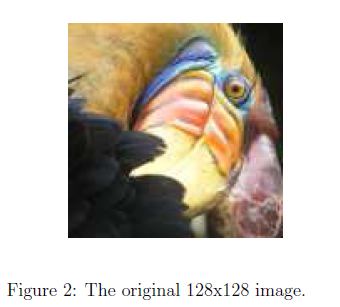

    In this exercise, you will use the *K*-means algorithm to select the 16 colors that will be used to represent the compressed image. Concretely, you will treat every pixel in the original image as a data example and use the *K*-means algorithm to find the 16 colors that best group (cluster) the pixels in the 3-dimensional RGB space. Once you have computed the cluster centroids on the image, you will then use the 16 colors to replace the pixels in the original image.

**The provided photo used in this exercise belongs to Frank Wouters and is used with his permission.*

#### 1.4.1 *K*-means on pixels

In MATLAB, images can be read in as follows:

This creates a three-dimensional matrix `A` whose first two indices identify a pixel position and whose last index represents red, green, or blue. For example, `A(50,33,3)` gives the blue intensity of the pixel at row 50 and column 33. The code below first loads the image, and then reshapes it to create an m by 3 matrix of pixel colors (where $m = 16384 = 128\times128$), and calls your *K*-means function on it.

%  Load an image of a bird
A = double(imread('bird_small.png'));
A = A / 255; % Divide by 255 so that all values are in the range 0 - 1

% Size of the image
img_size = size(A);

Reshape the image into an Nx3 matrix where N = number of pixels. Each row will contain the Red, Green and Blue pixel values. This gives us our dataset matrix X that we will use K-Means on.

X = reshape(A, img_size(1) * img_size(2), 3);

Run your K-Means algorithm on this data. You should try different values of K and max_iters here:

K = 16;
max_iters = 10;

When using K-Means, it is important the initialize the centroids randomly. You should complete the code in `kMeansInitCentroids.m` before proceeding

initial_centroids = kMeansInitCentroids(X, K);
% Run K-Means
[centroids, ~] = runkMeans(X, initial_centroids, max_iters);

K-Means iteration 1/10...


Unable to perform assignment because the size of the left side is 1-by-1 and the size of the right side is 2-by-1.

Error in findClosestCentroids (line 26)
    idx(i,1) = find(temp_dist == min(temp_dist));

Error in runkMeans (line 44)
    idx = findClosestCentroids(X, centroids);

    After finding the top $K = 16$ colors to represent the image, you can now assign each pixel position to its closest centroid using the `findClosestCentroids` function. This allows you to represent the original image using the centroid assignments of each pixel. Notice that you have signicantly reduced the number of bits that are required to describe the image. The original image required 24 bits for each one of the $128\times128$ pixel locations, resulting in total size of $128\times128\times24 = 393,216$ bits. 

    The new representation requires some overhead storage in form of a dictionary of 16 colors, each of which require 24 bits, but the image itself then only requires 4 bits per pixel location. The final number of bits used is therefore $16\times24 + 128\times128\times4 = 65,920$ bits, which corresponds to compressing the original image by about a factor of 6. 

% Find closest cluster members
idx = findClosestCentroids(X, centroids);

Matrix dimensions must agree.

Error in findClosestCentroids (line 25)
    temp_dist = sum((X(i,:)-centroids).^2, 2);

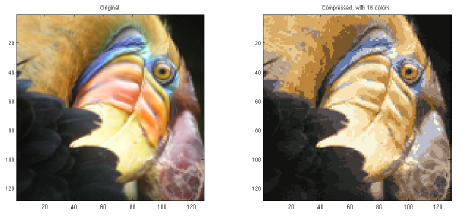

    Finally, you can view the effects of the compression by reconstructing the image based only on the centroid assignments. Specically, you can replace each pixel location with the mean of the centroid assigned to it. Figure 3 shows the reconstruction we obtained. Even though the resulting image retains most of the characteristics of the original, we also see some compression artifacts.

Essentially, now we have represented the image `X` as in terms of the indices in `idx`. We can now recover the image from the indices (`idx`) by mapping each pixel (specified by it's index in `idx`) to the centroid value.

X_recovered = centroids(idx,:);

% Reshape the recovered image into proper dimensions
X_recovered = reshape(X_recovered, img_size(1), img_size(2), 3);

Error using reshape
Number of elements must not change. Use [] as one of the size inputs to automatically calculate the appropriate size for that dimension.


% Display the original image 
figure;
subplot(1, 2, 1);
imagesc(A); 
title('Original');
axis square

% Display compressed image side by side
subplot(1, 2, 2);
imagesc(X_recovered)
title(sprintf('Compressed, with %d colors.', K));
axis square

*You do not need to make any submissions for this part of the exercise.*

### 1.5 Optional (ungraded) exercise: Use your own image

In this exercise, modify the code we have supplied to run on one of your own images. Note that if your image is very large, then *K*-means can take a long time to run. Therefore, we recommend that you resize your images to managable sizes before running the code. You can also try to vary `K` to see the effects on the compression.

## 2. Principal Component Analysis

In this exercise, you will use principal component analysis (PCA) to perform dimensionalty reduction. You will first experiment with an example 2D dataset to get intuition on how PCA works, and then use it on a bigger dataset of 5000 face image dataset. The code provided, will help you step through the first half of the exercise.

### 2.1 Example dataset

To help you understand how PCA works, you will first start with a 2D dataset which has one direction of large variation and one of smaller variation. The code below will plot the training data (Figure 4). 

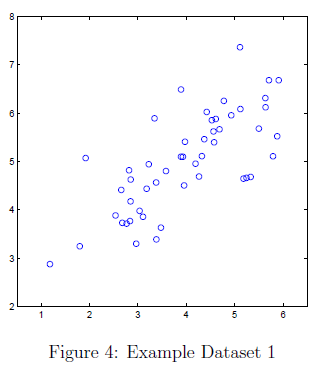

In this part of the exercise, you will visualize what happens when you use PCA to reduce the data from 2D to 1D. In practice, you might want to reduce data from 256 to 50 dimensions, say; but using lower dimensional data in this example allows us to visualize the algorithms better.

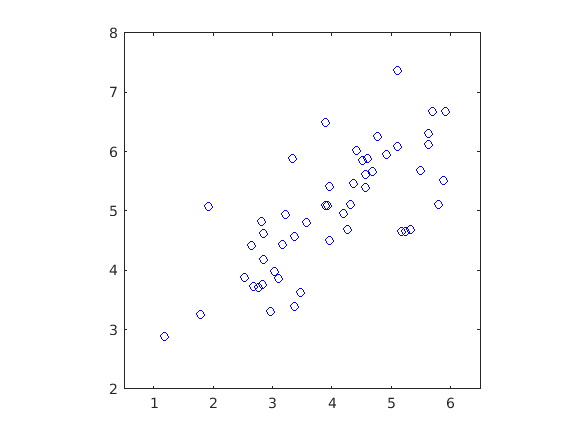

% Initialization
clear;
% The following command loads the dataset. You should now have the variable X in your environment
load ('ex7data1.mat');

% Visualize the example dataset
figure;
plot(X(:, 1), X(:, 2), 'bo');
axis([0.5 6.5 2 8]); axis square;

### 2.2 Implementing PCA

In this part of the exercise, you will implement PCA. PCA consists of two computational steps: First, you compute the covariance matrix of the data. Then, you use MATLAB's `svd` function to compute the eigenvectors $U_1, U_2,\ldots,U_n$. These will correspond to the principal components of variation in the data. Before using PCA, it is important to first normalize the data by subtracting the mean value of each feature from the dataset, and scaling each dimension so that they are in the same range. In the code below, this normalization has been performed for you using the `featureNormalize` function.

    After normalizing the data, you can run PCA to compute the principal components. You task is to complete the code in `pca.m` to compute the principal components of the dataset. First, you should compute the covariance matrix of the data, which is given by:


$$\Sigma =\frac{1}{m}X^T X$$


where $X$ is the data matrix with examples in rows, and $m$ is the number of examples. Note that $\Sigma$ is a $n \times n$ matrix and not the summation operator.

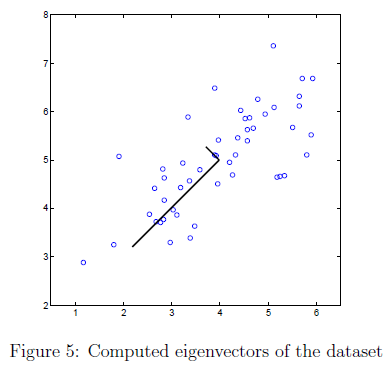

After computing the covariance matrix, you can run SVD on it to compute the principal components. In MATLAB, you can run SVD with the following command: 

where `U` will contain the principal components and `S` will contain a diagonal matrix. Once you have completed `pca.m`, the code below will run PCA on the example dataset and plot the corresponding principal components found (Figure 5). The script will also output the top principal component (eigenvector) found, and you should expect to see an output of about `[-0.707 -0.707]`. (It is possible that MATLAB may instead output the negative of this, since $U_1$ and $-U_1$ are equally valid choices for the first principal component.)

% Before running PCA, it is important to first normalize X
[X_norm, mu, ~] = featureNormalize(X);

% Run PCA
[U, S] = pca(X_norm);

% Draw the eigenvectors centered at mean of data. These lines show the directions of maximum variations in the dataset.
hold on;
drawLine(mu, mu + 1.5 * S(1,1) * U(:,1)', '-k', 'LineWidth', 2);
drawLine(mu, mu + 1.5 * S(2,2) * U(:,2)', '-k', 'LineWidth', 2);
hold off;


fprintf('Top eigenvector U(:,1) = %f %f \n', U(1,1), U(2,1));

Top eigenvector U(:,1) = -0.575434 -0.598651 


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

### 2.3 Dimensionality reduction with PCA

After computing the principal components, you can use them to reduce the feature dimension of your dataset by projecting each example onto a lower dimensional space, $x^{(i)}\rightarrow z^{(i)}$ (e.g., projecting the data from 2D to 1D). In this part of the exercise, you will use the eigenvectors returned by PCA and project the example dataset into a 1-dimensional space.

    In practice, if you were using a learning algorithm such as linear regression or perhaps neural networks, you could now use the projected data instead of the original data. By using the projected data, you can train your model faster as there are less dimensions in the input.

#### 2.3.1 Projecting the data onto the principal components

You should now complete the code in `projectData.m`. Specically, you are given a dataset `X`, the principal components `U`, and the desired number of dimensions to reduce to `K`. You should project each example in `X` onto the top `K` components in `U`. Note that the top `K` components in `U` are given by the first `K` columns of `U`, that is `U_reduce = U(:, 1:K)`.

Once you have completed the code in` projectData.m`, run the code below to project the first example onto the first dimension and you should see a value of about `1.481` (or possibly `-1.481`, if you got $-U_1$ instead of $U_1$).

% Project the data onto K = 1 dimension
K = 1;
Z = projectData(X_norm, U, K);
fprintf('Projection of the first example: %f\n', Z(1));

Projection of the first example: -1.198900


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.2 Reconstructing an approximation of the data

After projecting the data onto the lower dimensional space, you can approximately recover the data by projecting them back onto the original high dimensional space. Your task is to complete `recoverData.m` to project each example in `Z` back onto the original space and return the recovered approximation in `X_rec`. Once you have completed the code in `recoverData.m`, the code below will recover an approximation of the first example and you should see a value of about `[-1.047 -1.047]`.

X_rec  = recoverData(Z, U, K);
fprintf('Approximation of the first example: %f %f\n', X_rec(1, 1), X_rec(1, 2));

Approximation of the first example: 0.689888 0.717723


*You should now submit your solutions.  Enter *`submit`* at the command prompt, then and enter or confirm your login and token when prompted.*

#### 2.3.3 Visualizing the projections

After completing both `projectData` and `recoverData`, the code in this section will perform both the projection and approximate reconstruction to show how the projection affects the data. In Figure 6, the original data points are indicated with the blue circles, while the projected data points are indicated with the red circles. The projection effectively only retains the information in the direction given by $U_1$.

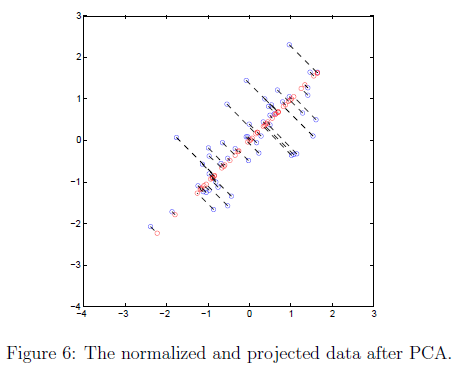

%  Plot the normalized dataset (returned from pca)
plot(X_norm(:, 1), X_norm(:, 2), 'bo');
axis([-4 3 -4 3]); axis square
%  Draw lines connecting the projected points to the original points
hold on;
plot(X_rec(:, 1), X_rec(:, 2), 'ro');
for i = 1:size(X_norm, 1)
    drawLine(X_norm(i,:), X_rec(i,:), '--k', 'LineWidth', 1);
end
hold off

### 2.4 Face image dataset

In this part of the exercise, you will run PCA on face images to see how it can be used in practice for dimension reduction. The dataset `ex7faces.mat` contains a dataset* `X` of face images, each $32 \times 32$ in grayscale. 

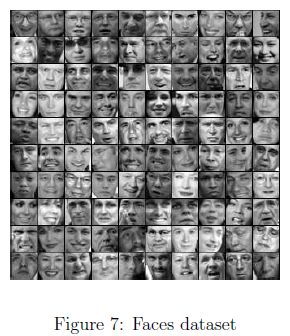

Each row of `X` corresponds to one face image (a row vector of length 1024). The code in this section will load and visualize the first 100 of these face images (Figure 7).

%  Load Face dataset
load ('ex7faces.mat')
%  Display the first 100 faces in the dataset
displayData(X(1:100, :));

**This dataset was based on a cropped version of the*[ *labeled faces in the wild dataset*](http://vis-www.cs.umass.edu/lfw/)*.*

#### 2.4.1 PCA on faces

To run PCA on the face dataset, we first normalize the dataset by subtracting the mean of each feature from the data matrix `X`. The code below will do this for you and then run your PCA code. After running PCA, you will obtain the principal components of the dataset. Notice that each principal component in `U` (each row) is a vector of length $n$ (where for the face dataset, $n = 1024$). It turns out that we can visualize these principal components by reshaping each of them into a $32 \times 32$ matrix that corresponds to the pixels in the original dataset. 

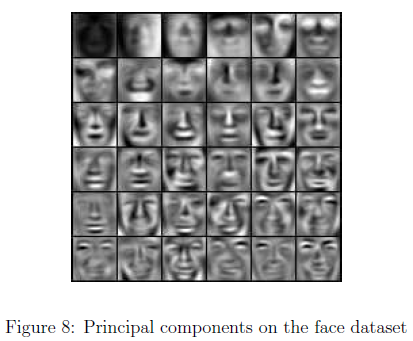

The code below displays the first 36 principal components that describe the largest variations (Figure 8).  If you want, you can also change the code to display more principal components to see how they capture more and more details. Before running PCA, it is important to first normalize `X` by subtracting the mean value from each feature.

[X_norm, ~, ~] = featureNormalize(X);

% Run PCA
[U, ~] = pca(X_norm);

% Visualize the top 36 eigenvectors found
displayData(U(:, 1:36)');

The code below will project the face dataset onto only the first 100 principal components. Concretely, each face image is now described by a vector $z^{(i)}\in\mathbb{R}^{100}$. 

K = 100;
Z = projectData(X_norm, U, K);

fprintf('The projected data Z has a size of: %d x %d', size(Z));

To understand what is lost in the dimension reduction, you can recover the data using only the projected dataset. In the code below, an approximate recovery of the data is performed and the original and projected face images are displayed side by side (Figure 9). 

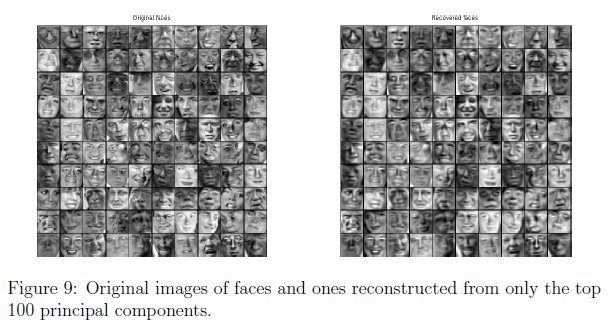

From the reconstruction, you can observe that the general structure and appearance of the face are kept while the fine details are lost. This is a remarkable reduction (more than $10\times$) in the dataset size that can help speed up your learning algorithm signicantly. For example, if you were training a neural network to perform person recognition (gven a face image, predict the identitfy of the person), you can use the dimension reduced input of only a 100 dimensions instead of the original pixels.

X_rec  = recoverData(Z, U, K);

% Display normalized data
subplot(1, 2, 1);
displayData(X_norm(1:100,:));
title('Original faces');
axis square;

% Display reconstructed data from only k eigenfaces
subplot(1, 2, 2);
displayData(X_rec(1:100,:));
title('Recovered faces');
axis square;

### 2.5 Optional (ungraded) exercise: PCA for visualization

In the earlier *K*-means image compression exercise, you used the *K*-means algorithm in the 3-dimensional RGB space. In this section, we have provided code to visualize the final pixel assignments in this 3D space using the `scatter3` function. Each data point is colored according to the cluster it has been assigned to. You can select the rotate icon and then drag your mouse on the figure to rotate and inspect this data in 3 dimensions.

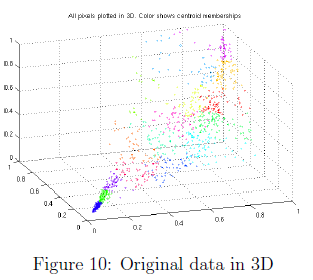

clear;
% Re-load the image from the previous exercise and run K-Means on it
% For this to work, you need to complete the K-Means assignment first
A = double(imread('bird_small.png'));
A = A / 255;
img_size = size(A);
X = reshape(A, img_size(1) * img_size(2), 3);
K = 16; 
max_iters = 10;
initial_centroids = kMeansInitCentroids(X, K);
[centroids, idx] = runkMeans(X, initial_centroids, max_iters);

%  Sample 1000 random indexes (since working with all the data is
%  too expensive. If you have a fast computer, you may increase this.
sel = floor(rand(1000, 1) * size(X, 1)) + 1;

%  Setup Color Palette
palette = hsv(K);
colors = palette(idx(sel), :);

%  Visualize the data and centroid memberships in 3D
figure;
scatter3(X(sel, 1), X(sel, 2), X(sel, 3), 10, colors);
title('Pixel dataset plotted in 3D. Color shows centroid memberships');

    It turns out that visualizing datasets in 3 dimensions or greater can be cumbersome. Therefore, it is often desirable to only display the data in 2D even at the cost of losing some information. In practice, PCA is often used to reduce the dimensionality of data for visualization purposes. In the code below, the script will apply your implementation of PCA to the 3-dimensional data to reduce it to 2 dimensions and visualize the result in a 2D scatter plot. The PCA projection can be thought of as a rotation that selects the view that maximizes the spread of the data, which often corresponds to the 'best' view.

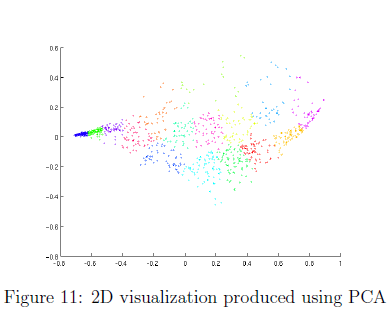

% Subtract the mean to use PCA
[X_norm, mu, sigma] = featureNormalize(X);

% PCA and project the data to 2D
[U, S] = pca(X_norm);
Z = projectData(X_norm, U, 2);

% Plot in 2D
figure;
plotDataPoints(Z(sel, :), idx(sel), K);
title('Pixel dataset plotted in 2D, using PCA for dimensionality reduction');

## Submission and Grading

After completing various parts of the assignment, be sure to use the submit function system to submit your solutions to our servers. The following is a breakdown of how each part of this exercise is scored. 

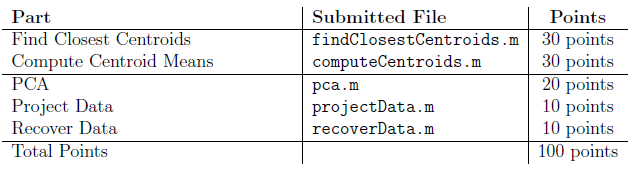

You are allowed to submit your solutions multiple times, and we will take only the highest score into consideration.